# **Kalman filter**

## Kalman filter for Asset replication

Here we intend to exploit Kalman filter for Asset replication. 

In the pursuit of delivering returns comparable to a specific index, a replication strategy emerges as a promising approach. By incorporating improved liquidity, transparency, and simplicity, this strategy seeks to enhance investment outcomes. Nevertheless, research has uncovered a tradeoff associated with utilizing more liquid and transparent replication methods, as they tend to underperform relative to the target index.

In this presentation, our focus is to explore the implementation of the Kalman Filter estimation algorithm in constructing a portfolio consisting of highly liquid contracts. The objective is to replicate or even outperform the returns of a designated index, referred to as the 'monster index.' This approach enables us to capitalize on the advantages of heightened transparency, simplicity, and improved liquidity while striving for superior investment outcomes.

### Kalman Filter Basics

The Kalman Filter is a powerful mathematical tool utilized in the estimation of hidden states, leveraging a sequence of noisy observations.

 • As a recursive algorithm, it produces optimal estimates of the state by assuming linearity in the state transition process and mappings to observable measurements.

 • With its ability to support estimations of past, present, and even future states, the Kalman Filter proves valuable in modeling systems even when their precise nature remains unknown.

## Asset Replication Bacics

In the realm of investments, asset replication revolves around mirroring the returns of a specific asset using the returns generated by another asset or a combination of multiple assets. This approach comes into play when the asset being replicated lacks direct tradability or desired liquidity. To gain exposure to the replicated asset or index, investors turn to alternative instruments such as cash instruments, derivatives, or exchange-traded funds (ETFs). These financial tools enable investors to achieve similar returns while navigating the constraints posed by the original asset's limited market accessibility or liquidity.

### Filter implementation

Follows the relative linear system:

We impose the weights of the futures to be constant in time, plus a certain noise due to the variance of the features' returns:

x(t+1) = x(t) + v1(t)

where x(t) is the state variable indicating the futures weights. 

We ask for equality of the returns between the index and the available futures, considering an additional noise:

y(t) = Ax(t) + v2(t) 

where A is the matrix of futures returns and v2(t), here, is supposed to be null, that means we suppose to perfectly measure the index returns. 

load("Official Pipeline\KF\InvestmentReplica.mat")
load("Official Pipeline\KF\variances.mat")

% Synthetic target weights
wHFRXGL = 0.5; 
wMXWO = 0.25;
wLEGATRUU = 0.25;

% Define the state variables
x = [wHFRXGL wMXWO wLEGATRUU];

% Building the target, observation variables 
y = wHFRXGL*price2ret(HFRXGL) + wMXWO*price2ret(MXWO) + wLEGATRUU*price2ret(LEGATRUU); % "Monster Index" returns

% Futures returns
X = [price2ret(CO1) price2ret(DU1) price2ret(ES1) price2ret(GC1)...
           price2ret(NQ1) price2ret(RX1) price2ret(TP1)...
           price2ret(TU2) price2ret(TY1) price2ret(VG1)];
% Remark: we have neglected LLL1 returns because of anomalies in prices
% evolution


Let's try with a simplified version of the KF where the noises are estimated by sampled variances. 

%Setting rolling window and initial parameters 
rollingWindow = 52; 
i = 1;
b = zeros(size(X,2));
bENet2 = [];
rENet2 = [];
GrossExposure = [];
endSample = 0;
warning('off','all'); % avoid annoying warnings during the loop

% Calculation of weights by appropriately shifting the considered rolling window
while endSample <= (length(X) - 2)
    startSample = i;
    endSample = i+rollingWindow-1;
   
    % Set up the state-space model 
    m = 10;
    F = eye(m);
    H = X(startSample:endSample,:); % time-depending 
    V2 = zeros(156,1);
    V1 = eye(m).*var(X(startSample:endSample,:))';

    %Initialization 
    x_0 = zeros(1,m);
    P = ones(m,m);
    F = eye(m,m);
    y_meas = y(startSample:endSample); %time-depending
    x_corr = zeros(length(y_meas), m);
    x_pred = zeros(length(y_meas), m);
    x_pred(1,:) = x_0;
    K = zeros(m,length(y_meas));
 

    for t = 1:length(y_meas)
      % Correction step
      [K_t, x_corr_t] = kf_correction(y_meas, H, V2, x_pred,P,t,F);
      K(:,t) = K_t;
      x_corr(t,:) = x_corr_t;
      % Prediction step
      [x_pred_t, P_pred] = kf_prediction(F, V1, x_corr_t, P, H,t);
      P = P_pred;
      x_pred(t,:) = x_pred_t;
    end

    b = x_pred_t;
    GrossExposure = [GrossExposure; sum(abs(b))];
    bENet2 = [bENet2; b];
    r = X(endSample + 1,:)*b';
    rENet2 = [rENet2; r];
    i = i+1;
end

warning('on','all'); % warnings on again

 Let's visually compare the prices of the target index with the computed replica

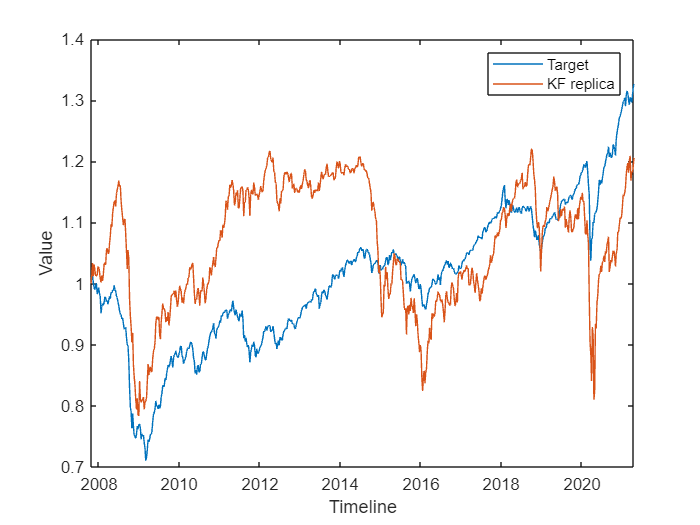

replRetKF = X*b'; % compute portfolio returns using regression coefficients as weights
repKF = ret2price(replRetKF); % from returns to levels

figure
plot(XTab.Date,ret2price(y),'DisplayName','Target');
hold on;
plot(XTab.Date,repKF,'DisplayName','KF replica');
xlabel('Timeline')
ylabel('Value')
legend
hold off;

### Preliminary KF Portofolio Replication Results

Already at a visual level, it is evident that a refinement of the replication technique is necessary, particularly through a meticulous sensitivity analysis of the filter.

We can assess this inadequacy by calculating the tracking error and info ratio

% Avarage tracking error
[InfoRatio, TrackingError] = inforatio(replRetKF, y)

InfoRatio = -0.0092

TrackingError = 0.0147

## Sensitivity analysis

The underlying concept is that the only degree of freedom available to enhance the Kalman filter is to manipulate the noise by conducting a sensitivity analysis. In this case, exploring a variance estimation model enables a reduction in estimation error.

## EGARCH MODEL FOR VARIANCE ESTIMATION

The Generalized Autoregressive Conditional Heteroskedasticity (GARCH) model is a statistical model used for estimating and forecasting the variance of a time series. It is an extension of the autoregressive moving average (ARMA) model, which captures the linear dependencies in a time series. However, the GARCH model also takes into account the conditional heteroskedasticity, meaning that the variance of the series is not constant over time but depends on past observations. The GARCH model is estimated by fitting the model parameters to the observed data using methods such as maximum likelihood estimation. Once the model is estimated, it can be used to estimate and forecast the conditional variance of the time series. These estimates can be valuable for risk management, portfolio optimization, option pricing, and other applications in finance. 

The Exponential Generalized Autoregressive Conditional Heteroskedasticity (EGARCH) model is an extension of the GARCH model that addresses asymmetry and leverage effects in the conditional variance of a time series.

Let's start by converting data into timetable format. We consider each future separately. 

% T1 = timetable(Date,ret2price(X(:,1)));
% T2 = timetable(Date,ret2price(X(:,2)));
% T3 = timetable(Date,ret2price(X(:,3)));
% T4 = timetable(Date,ret2price(X(:,4)));
% T6 = timetable(Date,ret2price(X(:,6)));
% T7 = timetable(Date,ret2price(X(:,7)));
% T8 = timetable(Date,ret2price(X(:,8)));
% T9 = timetable(Date,ret2price(X(:,9)));
% T10 = timetable(Date,ret2price(X(:,10)));
% T11 = timetable(Date,ret2price(X(:,11)));
% 
% mdl1 = EGARCH_Logreturns1;
% V1 = infer(mdl1,Logreturns1); % Infer conditional variance
% mdl2 = EGARCH_Logreturns2;
% V2 = infer(mdl2,Logreturns2); % Infer conditional variance
% mdl3 = EGARCH_Logreturns3;
% V3 = infer(mdl3,Logreturns3); % Infer conditional variance
% mdl4 = EGARCH_Logreturns4;
% V4 = infer(mdl4,Logreturns4); % Infer conditional variance
% mdl6 = EGARCH_Logreturns6;
% V6 = infer(mdl6,Logreturns6); % Infer conditional variance
% mdl7 = EGARCH_Logreturns7;
% V7 = infer(mdl7,Logreturns7); % Infer conditional variance
% mdl8 = EGARCH_Logreturns8;
% V8 = infer(mdl8,Logreturns8); % Infer conditional variance
% mdl9 = EGARCH_Logreturn9;
% V9 = infer(mdl9,Logreturn9); % Infer conditional variance
% mdl10 = EGARCH_Logreturns10;
% V10 = infer(mdl10,Logreturns10); % Infer conditional variance
% mdl11 = EGARCH_Logreturns11;
% V11 = infer(mdl11,Logreturns11); % Infer conditional variance

Perform time series modeling using Econometrics Modeler App:

 % econometricModeler

- The chart is automatically reported. We invert prices into returns just performing logarithmic and differences transformations. 

- We see that the logreturns exhibit conditional error heteroscedasticity ( autocorrelation in the square series ). 

- We perform Engle's ARCH test to prove heteroscedasticity. The null hypothesis is that Logreturns exhibits no ARCH effects. It's rejected.

-  Then we perform a GARCH ( one-one ), the EGARCH and GJR. Looking at the goodness of fit, we observe the model with lowest AIC and BIC is the EGARCH. 

- Finally, we perform residual diagnostics with Q-Q plot. The residuals are approximately normal. 

%  variances = [V1 V2 V3 V4 V6 V7 V8 V9 V10 V11]; % varianze condizionali 

**To streamline data processing and avoid the need to use the tool every time, the conditioned variance matrix has been saved and loaded at the beginning of the notebook.**

Now, we run again the fillter with the new estimated conditional variances.

rollingWindow = 52; % in weeks (52 = 1Y, 104 = 2Y...)
i = 1;
b = zeros(size(X,2));
bENet2 = [];
rENet2 = [];
GrossExposure = [];
endSample = 0;
warning('off','all'); % avoid annoying warnings during the loop

while endSample <= (length(X) - 2)
    startSample = i;
    endSample = i+rollingWindow-1;
   
    % Set up the state-space model 
    m = 10;
    F = eye(m);
    H = X(startSample:endSample,:); % time-depending 
   % V2 = ones(156,1).*std(y(startSample:endSample));
    V2 = zeros(156,1);
    %V1 = eye(m).*var(X(startSample:endSample,:))';

    %Initialization 
    x_0 = zeros(1,m);
    P = ones(m,m);
    F = eye(m,m);
    y_meas = y(startSample:endSample); %time-depending
    x_corr = zeros(length(y_meas), m);
    x_pred = zeros(length(y_meas), m);
    x_pred(1,:) = x_0;
    K = zeros(m,length(y_meas));
  
 

    for t = 1:length(y_meas)
      V1 = eye(m).*variances(t);
      % Correction step
      [K_t, x_corr_t] = kf_correction(y_meas, H, V2, x_pred,P,t,F);
      K(:,t) = K_t;
      x_corr(t,:) = x_corr_t;
      % Prediction step
      [x_pred_t, P_pred] = kf_prediction(F, V1, x_corr_t, P, H,t);
      P = P_pred;
      x_pred(t,:) = x_pred_t;
    end

    b = x_pred_t;
    GrossExposure = [GrossExposure; sum(abs(b))];
    bENet2 = [bENet2; b];
    r = X(endSample + 1,:)*b';
    rENet2 = [rENet2; r];
    i = i+1;
end

warning('on','all'); % warnings on again

 Let's visually compare the prices of the target index with the computed replica

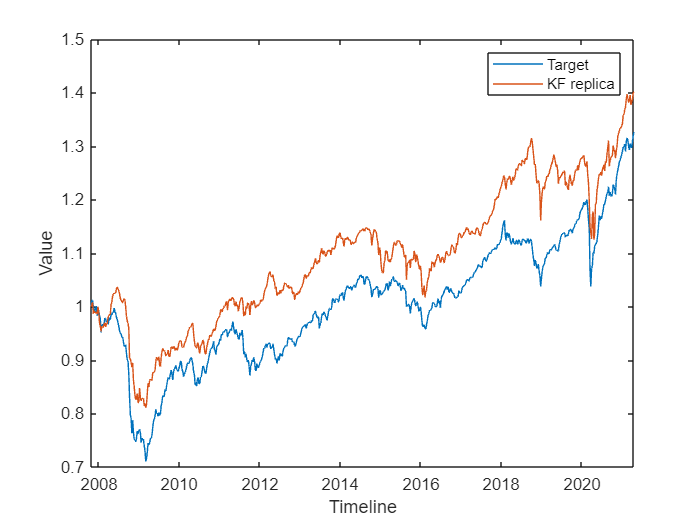

replRetKF = X*b'; % compute portfolio returns using regression coefficients as weights
repKF = ret2price(replRetKF); % from returns to levels

figure
plot(XTab.Date,ret2price(y),'DisplayName','Target');
hold on;
plot(XTab.Date,repKF,'DisplayName','KF replica');
xlabel('Timeline')
ylabel('Value')
legend
hold off;

At a graphical level, a significant improvement is already evident in the replica portfolio, which closely tracks the prices of the target index. The decision to incorporate correlations in the futures variances has proven to be an effective technique.

## Performance analysis

Before delving into the statistical and financial analysis of the latter portfolio, let us verify if there is sufficient evidence to discard the former in favor of the latter by comparing tracking error and information ratio.

% Avarage tracking error
[InfoRatio, TrackingError] = inforatio(replRetKF, y)

InfoRatio = 0.0102

TrackingError = 0.0077

Previous values were InfoRatio = -0.0092 and TrackingError = 0.0147. We have evidence that this new KF outperforms the former one. 

Now, let's deepen the statistical and financial analysis. 

#### MSE

% MSE
mse(y-replRetKF)

ans = 5.9318e-05

#### Tracking Error Volatility (TEV)

Tracking Error Volatility = (annualized) standard deviation of Tracking Error.

TE = rENet2 - y(rollingWindow + 1: end); % tracking error
TEV = std(TE)*sqrt(52)

TEV = 0.0544

#### Mean Annual Turnover

Turnover = calcTurnover(bENet2); % weekly turnover
meanTurnover = mean(Turnover)*52 % average annual turnover

meanTurnover = 10.0275

#### Mean Annual Trading costs

tradingCosts = 0.0004; % transaction costs (hp: buyCosts=sellCost)
meanTradingCosts = meanTurnover*tradingCosts

meanTradingCosts = 0.0040

The replica portfolio, constructed using a Kalman filter, demonstrates a favorable performance. With an average tracking error of 0.0077 and a low mean squared error (MSE) of 5.9318e-5, it accurately replicates the target index. The tracking error volatility (TEV) of 0.0544 indicates stability over time. However, the relatively high mean turnover annual of 10.0275 suggests increased transaction costs. Despite this drawback, the replica portfolio exhibits strong tracking capabilities and precision in mirroring the index, making it an appealing investment option.

## **Conclusions**

In summary, the replica portfolio, constructed using the Kalman filter, exhibits a commendable tracking performance with low tracking error and MSE. The stability of the tracking error volatility adds to its appeal. However, the relatively high turnover and associated trading costs should be carefully evaluated as potential drawbacks.

## VaR Analysis

After verifying the replication performance of the Kalman filter, let us proceed with a comparison of the risk measurement between the Kalman filter and the regression technique that has exhibited greater accuracy throughout the project synopsis: the elastic net. 

Value at Risk (VaR) analysis is commonly regarded as a risk measurement tool due to its ability to quantify the potential loss or downside risk associated with an investment or portfolio.

**Value at risk with historical simulation**

We start by considering Historical99 and Historical95 ( Value at Risk ) measures, which are used to estimate the potential loss of a portfolio at specified confidence level, tipically 99% and 95%, respectively. Historical VaR is calculated based on historical data, specifically the historical returns of the portfolio being analyzed. 

### Elastic Net Historical VaR 

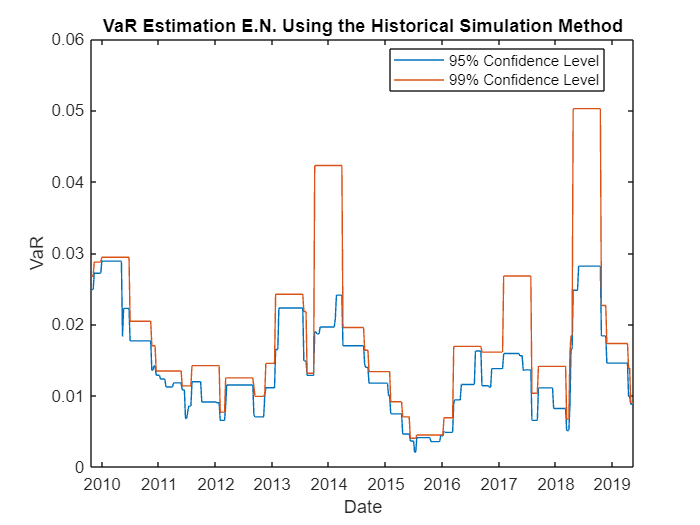

% load returns predicted by Elastic Net technique
load("y_pred_Enet.csv");

Returns = price2ret(y_pred_Enet);
DateReturns = Date(rollingWindow+1:end);
SampleSize = length(Returns);

TestWindowStart      = rollingWindow+1;
TestWindow           = TestWindowStart : SampleSize;
EstimationWindowSize = rollingWindow/2; %fare ricerca su dimensioni più adeguate

pVaR = [0.05 0.01];

Historical95_en = zeros(length(TestWindow),1);
Historical99_en = zeros(length(TestWindow),1);

for t = TestWindow
    i = t - TestWindowStart + 1;
    EstimationWindow = t-EstimationWindowSize:t-1;
    X = Returns(EstimationWindow);
    Historical95_en(i) = -quantile(X,pVaR(1)); 
    Historical99_en(i) = -quantile(X,pVaR(2)); 
end

figure;
plot(DateReturns(TestWindow),[Historical95_en Historical99_en])
ylabel('VaR')
xlabel('Date')
legend({'95% Confidence Level','99% Confidence Level'},'Location','Best')
title('VaR Estimation E.N. Using the Historical Simulation Method')

### Kalman filter Historical VaR

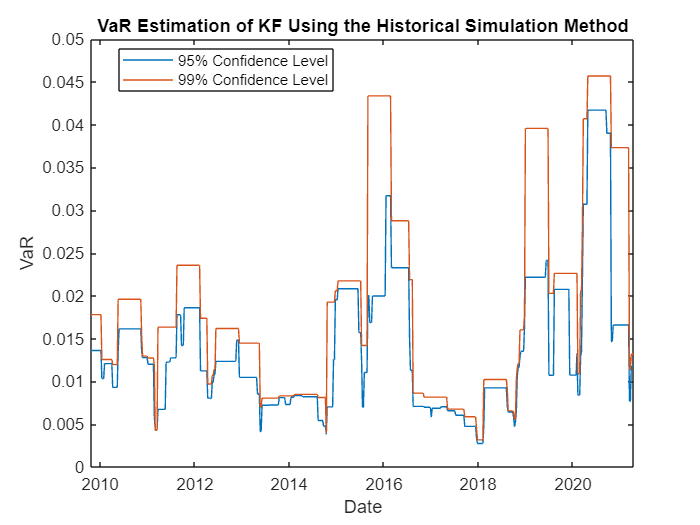

Returns1 = replRetKF(rollingWindow:end); 
DateReturns = Date(rollingWindow+1:end);
SampleSize = length(Returns1);

TestWindowStart      = rollingWindow+1;
TestWindow           = TestWindowStart : SampleSize;
EstimationWindowSize = rollingWindow/2; 

pVaR = [0.05 0.01];

Historical95_kf = zeros(length(TestWindow),1);
Historical99_kf = zeros(length(TestWindow),1);

for t = TestWindow
    i = t - TestWindowStart + 1;
    EstimationWindow = t-EstimationWindowSize:t-1;
    X = Returns1(EstimationWindow);
    Historical95_kf(i) = -quantile(X,pVaR(1)); 
    Historical99_kf(i) = -quantile(X,pVaR(2)); 
end

figure;
plot(DateReturns(TestWindow),[Historical95_kf Historical99_kf])
ylabel('VaR')
xlabel('Date')
legend({'95% Confidence Level','99% Confidence Level'},'Location','Best')
title('VaR Estimation of KF Using the Historical Simulation Method')

## **About it **

As regards Historical95, the provided values for the Elastic Net method range between 0.0021 and 0.0289, while the Kalman Filter method values range from 0.0027 to 0.0417. As regards Historical99, it's between 0.0040 and 0.0502 for the Elastic net method and between 0.0032 and  0.0457 for Kalman Filter. It is notable that the Elastic Net method consistently yields higher VaR values when compared to the Kalman Filter method.

A lower VaR value is indicative of a lower expected risk and a more favorable risk-return profile. Consequently, these findings suggest that the portfolio regressed using the Kalman Filter method exhibits lower risk in comparison to the one utilizing the Elastic Net method. This observation implies that the Kalman Filter method may offer a more accurate estimation of the portfolio's potential downside risk based on historical data, which in turn could be advantageous for risk management and decision-making purposes.

**VaR Estimation Using the EWMA Method**

We, then, calculate VaR using the EWMA method. The EWMA method is a statistical technique that incorporates historical data to calculate the potential losses a portfolio or investment may face within a specified time frame.

The process involves assigning weights to past observations, with more recent data points given higher importance. This weighting scheme allows the model to give greater emphasis to recent market conditions, which are considered more relevant for estimating future risk.

#### Elastic net EWMA method

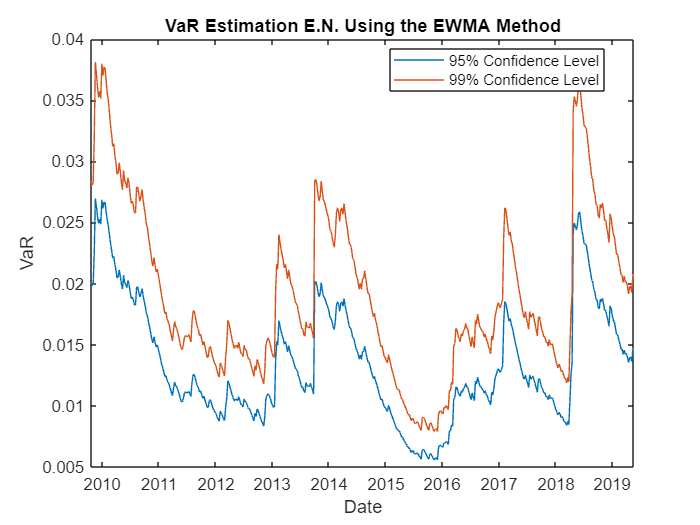

Lambda = 0.94; %frequently used in practice
SampleSize = length(Returns);
TestWindowStart      = rollingWindow+1;
TestWindow = TestWindowStart : SampleSize;
Sigma2     = zeros(length(Returns),1);
Sigma2(1)  = Returns(1)^2;

for i = 2 : (TestWindowStart-1)
    Sigma2(i) = (1-Lambda) * Returns(i-1)^2 + Lambda * Sigma2(i-1); %extimation of the variance
end

Zscore = norminv(pVaR);
EWMA95_en = zeros(length(TestWindow),1);
EWMA99_en = zeros(length(TestWindow),1);

for t = TestWindow 
    k     = t - TestWindowStart + 1;
    Sigma2(t) = (1-Lambda) * Returns(t-1)^2 + Lambda * Sigma2(t-1);
    Sigma = sqrt(Sigma2(t));
    EWMA95_en(k) = -Zscore(1)*Sigma;
    EWMA99_en(k) = -Zscore(2)*Sigma;
end

figure;
plot(DateReturns(TestWindow),[EWMA95_en EWMA99_en])
ylabel('VaR')
xlabel('Date')
legend({'95% Confidence Level','99% Confidence Level'},'Location','Best')
title('VaR Estimation E.N. Using the EWMA Method')

**Kalman Filter EMWA method**

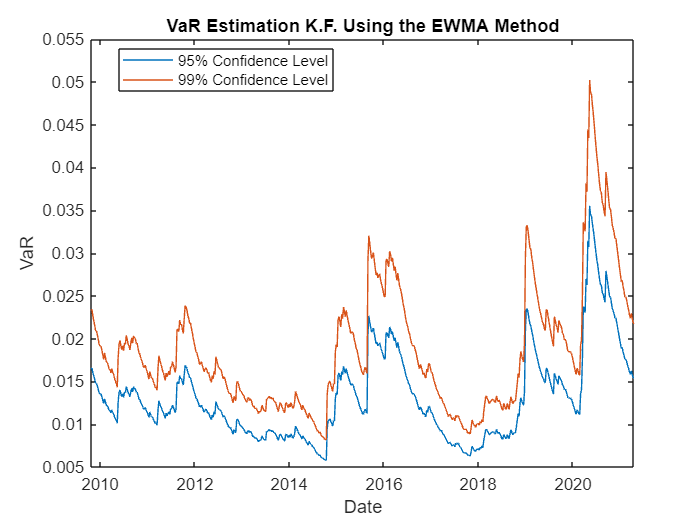

Lambda = 0.94; %frequently used in practice
SampleSize = length(Returns1);
TestWindowStart      = rollingWindow+1;
TestWindow           = TestWindowStart : SampleSize;
Sigma2     = zeros(length(Returns1),1);
Sigma2(1)  = Returns1(1)^2;

for i = 2 : (TestWindowStart-1)
    Sigma2(i) = (1-Lambda) * Returns1(i-1)^2 + Lambda * Sigma2(i-1); %extimation of the variance
end

Zscore = norminv(pVaR);
EWMA95_kf = zeros(length(TestWindow),1);
EWMA99_kf = zeros(length(TestWindow),1);

for t = TestWindow 
    k     = t - TestWindowStart + 1;
    Sigma2(t) = (1-Lambda) * Returns1(t-1)^2 + Lambda * Sigma2(t-1);
    Sigma = sqrt(Sigma2(t));
    EWMA95_kf(k) = -Zscore(1)*Sigma;
    EWMA99_kf(k) = -Zscore(2)*Sigma;
end

figure;
plot(DateReturns(TestWindow),[EWMA95_kf EWMA99_kf])
ylabel('VaR')
xlabel('Date')
legend({'95% Confidence Level','99% Confidence Level'},'Location','Best')
title('VaR Estimation K.F. Using the EWMA Method')

## **About it **

As regards EMWA 95% Confidence Level, the provided values for the Elastic Net method range between 0.0056 and 0.0269, while the Kalman Filter method values range from 0.0058 to 0.0355. As regards EMWA 99% Confidence Level, it's between 0.0079 and 0.0381 for the Elastic net method and between 0.0082 and  0.0502 for Kalman Filter.

In this context, the Kalman Filter method may incorporate recent observations that exhibit higher volatility or risk, leading to higher EWMA VaR values compared to the Elastic Net method. It suggests that the two portfolios may have different sensitivities to recent market dynamics and the weighting schemes used in the VaR estimation.

### Graphical VaR comparison

**VaR at 95% Elastic Net**

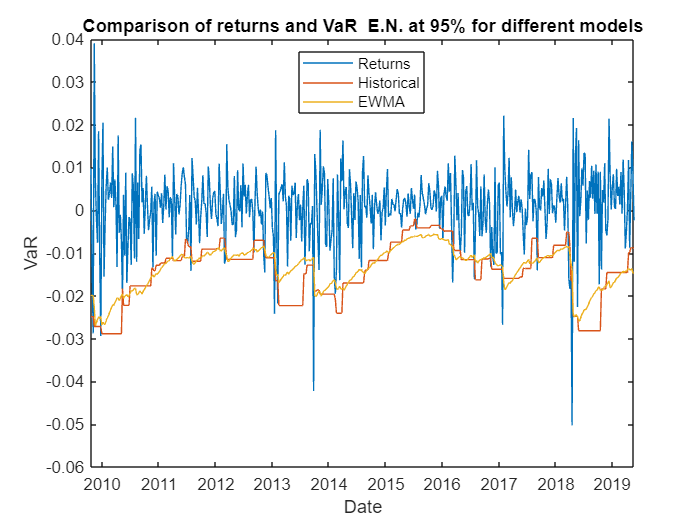

SampleSize = length(Returns);
TestWindowStart      = rollingWindow+1;
TestWindow = TestWindowStart : SampleSize;
ReturnsTest = Returns(TestWindow);
DatesTest   = DateReturns(TestWindow);
figure;
plot(DatesTest,[ReturnsTest -Historical95_en -EWMA95_en])
ylabel('VaR')
xlabel('Date')
legend({'Returns','Historical','EWMA'},'Location','Best')
title('Comparison of returns and VaR  E.N. at 95% for different models')

**VaR at 99% Elastic Net**

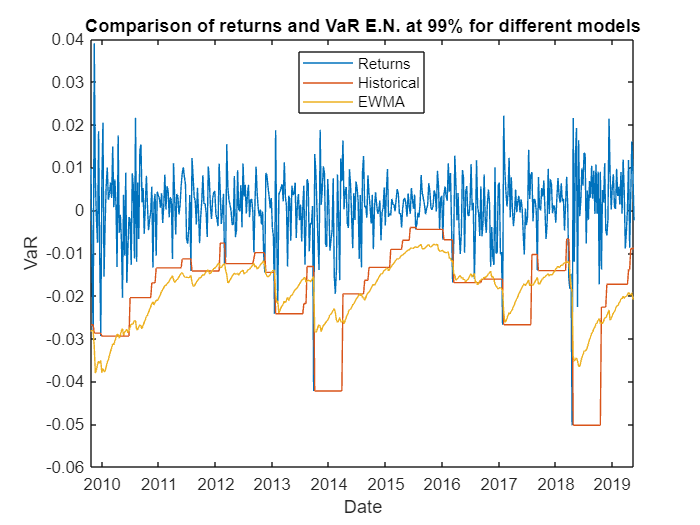

figure;
plot(DatesTest,[ReturnsTest -Historical99_en -EWMA99_en])
ylabel('VaR')
xlabel('Date')
legend({'Returns','Historical','EWMA'},'Location','Best')
title('Comparison of returns and VaR E.N. at 99% for different models')

**VaR at 95% Kalman Filter**

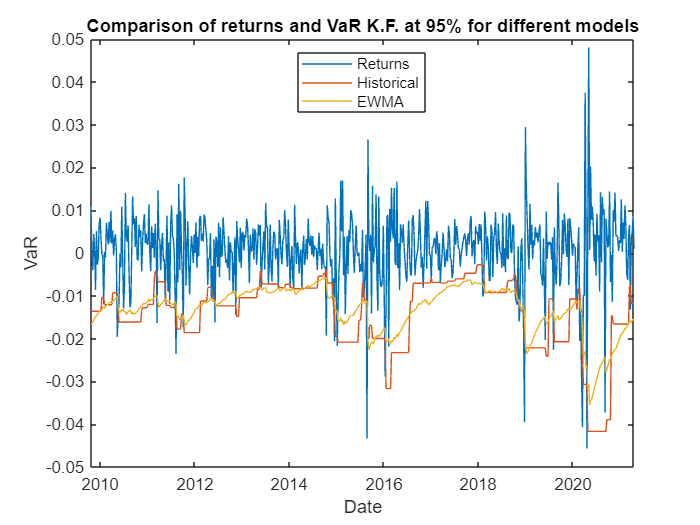

SampleSize = length(Returns1);
TestWindowStart      = rollingWindow+1;
TestWindow           = TestWindowStart : SampleSize;
ReturnsTest = Returns1(TestWindow);
DatesTest   = DateReturns(TestWindow);
figure;
plot(DatesTest,[ReturnsTest -Historical95_kf -EWMA95_kf])
ylabel('VaR')
xlabel('Date')
legend({'Returns','Historical','EWMA'},'Location','Best')
title('Comparison of returns and VaR K.F. at 95% for different models')

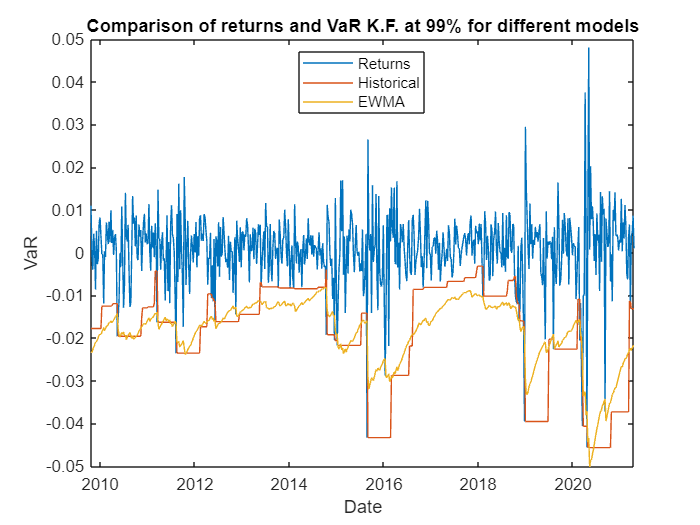

figure;
plot(DatesTest,[ReturnsTest -Historical99_kf -EWMA99_kf])
ylabel('VaR')
xlabel('Date')
legend({'Returns','Historical','EWMA'},'Location','Best')
title('Comparison of returns and VaR K.F. at 99% for different models')

#### Correction function

function [K_t, x_corr] = kf_correction(y_meas, H, V2, x_pred, P,t,F)
% Correction step of the Kalman filter. Given the predicted state x_pred and
% its variance, both are corrected based on the measurements.
% Inputs:
%   - y_meas: current measured output
%   - H: state-to-output matrix 
%   - V2: covariance of the measurement noise 
%   - x_pred: predicted state at the previous time step
%   - P: predicted covaraince of the state at the pevious time step 
%   - m: state length 
%   - t: current time step 
% Outputs:
%   - K: updated Kalman filter gain
%   - x_corr: corrected state estimate
%   - P_corr: corrected covariance of the state

    K_t = (F*P*H(t,:)')/(H(t,:)*P*H(t,:)' + V2(t)); % Update the Kalman filter gain [11x1]
   % P_corr = (eye(m) - K_t*H(t,:))*P; % Correct the state variance based on the new Kalman gain.
    x_corr = x_pred(t,:) + (y_meas(t) - H(t,:)*x_pred(end,:)')*K_t'; % Correct the state estimate based on the current measurement
end

#### Prediction function

function [x_pred, P_pred] = kf_prediction(F, V1, x_corr, P, H,t)
% Prediction step of the Kalman filter. Given the corrected state x_corr and
% its variance, both are predicted based on the system's model.
% Inputs:
%   - F: state transition matrix 
%   - V1: covariance of the process noise
%   - x_corr: corrected state at the previous time step
%   - P: corrected covaraince of the state at the pevious time step 
% Outputs:
%   - x_pred: predicted state estimate
%   - P_pred: predicted variance of the state
    
    x_pred = x_corr*F;
    P_pred = (F*P*F' + V1) - (F*P*H(t,:)')*inv((H(t,:)*P*H(t,:)'))*((F*P*H(t,:)'))';
end